## **1.5 **Implementing a First-Order Difference Equation

    Discrete-time systems are often implemented with linear constant-coefficient difference equations. Two very simple difference equations are the first-order moving average

y[n] = x[n] + b * x[n - 1], *(1.5)*

and the first-order autoregression

y[n] = a * y[n - 1] + x[n]. *(1.6)*

    Even these simple systems can be used to model or approximate a number of practical systems. For instance, the first-order autoregression can be used to model a bank account, where y[n] is the balance at time n, x[n] is the deposit or withdrawal at time n, and a = 1 + r  is the compounding due to interest rate r. In this exercise, you will be asked to write a function which implements the first-order autoregression equation. You will then be asked to test and analyze your function on some example systems.

### Advanced Problems

#### **(a)**

    Write a function *y = diffeqn(a, x, yn1)* which computes the output y[n] of the causal system determined by Eq. (1.6). The input vector x contains x[n] for 0 <= n <= N - 1 and yn1 supplies the value of y[-1]. The output vector y contains y[n] for 0 <= n <= N - 1. The first line of your M-file should read

*function y = diffeqn(a, x, yn1)*

    **Hint**: Note that y[-1] is necessary for computing y[0], which is the first step of the autoregression. Use a for loop in your M-file to compute y[n] for successively larger values of n, starting with n = 0.

% diffequ.m can be seen at the end of this report.

#### **(b)**

    Assume that a = 1, y[-1] = 0, and that we are only interested in the output over the interval 0 <= n <= 30. Use your function to compute the response due to x1[n] = δ[n]  and x2[n] = u[n], the unit impulse and unit step, respectively. Plot each response using *stem*.

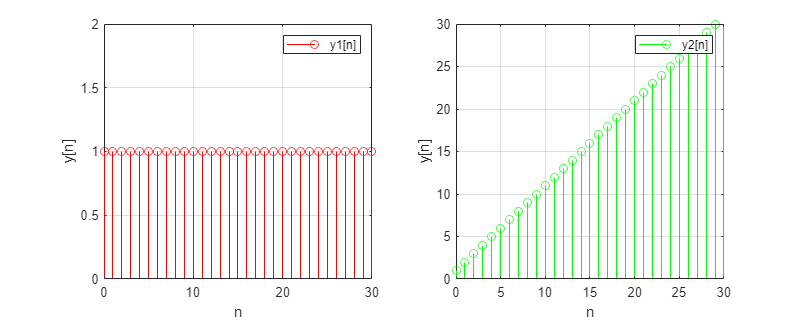

clear;

l = 0;
r = 30;
n = l : r;
a = 1;
yn1 = 0;

x1 = Impulse(n);
x2 = Step(n);
y1 = diffeqn(a, x1, yn1);
y2 = diffeqn(a, x2, yn1);

figure(1);
set(gcf, 'position', [0 0 800 320]);
d = [l, r];

subplot(1, 2, 1);
stem(n, y1, 'r');
legend('y1[n]');
grid on, xlim(d), ylim([0 2]), ylabel('y[n]'), xlabel('n');

subplot(1, 2, 2);
stem(n, y2, 'g');
legend('y2[n]');
grid on, xlim(d), ylim([0 30]), ylabel('y[n]'), xlabel('n');

    **Conclusion** Text.

#### **(c)**

    Assume again that a = 1, but that y[-1] = -1. Use your function to compute y[n] over 0 <= n <= 30 when the inputs are x1[n] = u[n] and x2[n] = 2 * u[n]. Define the outputs produced by the two signals to be y1[n] and y2[n], respectively. Use *stem* to display both outputs. Use *stem* to plot (2 * y1[n] - y2[n]). Given that Eq. (1.6) is a linear difference equation, why isn't this difference identically zero?

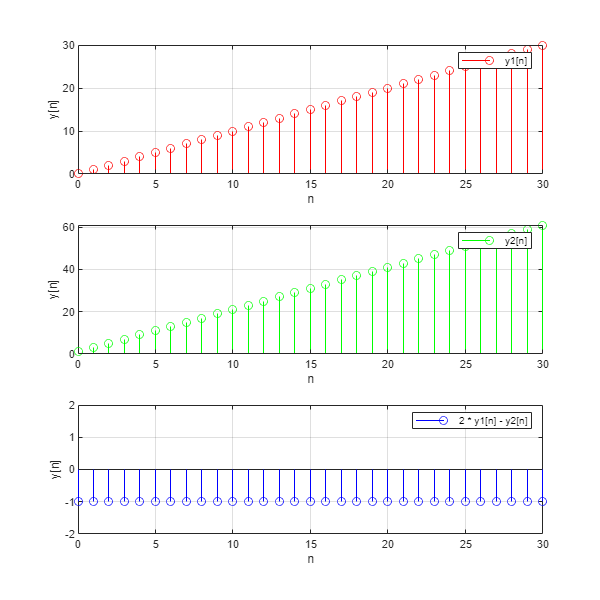

clear;

l = 0;
r = 30;
n = l : r;
a = 1;
yn1 = -1;

x1 = Step(n);
x2 = Step(n) * 2;
y1 = diffeqn(a, x1, yn1);
y2 = diffeqn(a, x2, yn1);

figure(2);
set(gcf, 'position', [0 0 600 600]);
d = [l, r];

subplot(3, 1, 1);

stem(n, y1, 'r');
legend('y1[n]');
grid on, xlim(d), ylim([0 30]), ylabel('y[n]'), xlabel('n');

subplot(3, 1, 2);

stem(n, y2, 'g');
legend('y2[n]');
grid on, xlim(d), ylim([0 61]), ylabel('y[n]'), xlabel('n');

subplot(3, 1, 3);

stem(n, 2 * y1 - y2, 'b');
legend('2 * y1[n] - y2[n]');
grid on, xlim(d), ylim([-2 2]), ylabel('y[n]'), xlabel('n');

    **Conclusion** Text.

#### **(d)**

    The causal systems described by Eq. (1.6) are BIBO (bounded-input bounded-output) stable whenever |a| < 1. A property of these stable systems is that the effect of the initial condition becomes insignificant for sufficiently large n. Assume a = 1 / 2  and that x contains x[n] = u[n] for 0 <= n <= 30. Assuming both y[-1] = 0 and  y[-1] = 1 / 2, compute the two output signals y[n] for 0 <= n <= 30. Use *stem* to display both responses. How do they differ?

clear;

l = 0;
r = 30;
n = l : r;
a = 1 / 2;

x1 = Step(n);
x2 = Step(n);
y1 = diffeqn(a, x1, 0);
y2 = diffeqn(a, x2, 1 / 2);

figure(3);
set(gcf, 'position', [0 0 640 320]);
d = [l, r];

stem(n, y2, 'bx'), stem(n, y1, 'r');
legend('y1[n] (y[-1] = 0)', 'y2[n] (y[-1] = 1 / 2)');

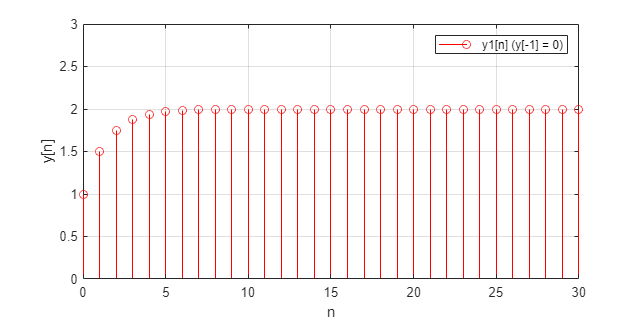

hold on, grid on, xlim(d), ylim([0 3]), ylabel('y[n]'), xlabel('n');

    **Conclusion** Text.

function y = diffeqn(a, x, yn1)
    y = a * yn1 + x(1);
    for k = x(2 : end) y = [y, a * y(end) + k]; end
end

function delta = Impulse(n) % DT Unit Impulse Signal
    delta = zeros(1, length(n));
    delta(n == 0) = 1;
end

function u = Step(n) % DT Unit Step Signal
    u = zeros(1, length(n)) + (n >= 0);
end